# Transfer Learning Using AlexNet  - 2702

Requirements:

Deep Learning Toolbox

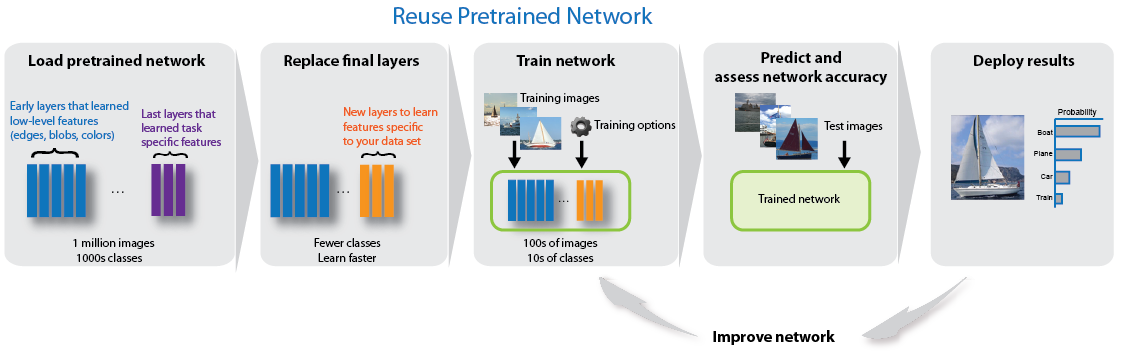

## Load Data

imds = imageDatastore('dataset\2702_Section_Categories\Car_Section_1', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
imds.ReadFcn = @customreader;
[imds1,imds2]=splitEachLabel(imds,min(groupcounts(imds.Labels)),'randomized');
info= countEachLabel(imds1)

info = 2×2 table
        Label         Count
    ______________    _____

    No_Traffic Jam     626 
    Traffic Jam        626 


## Visualize the dataset

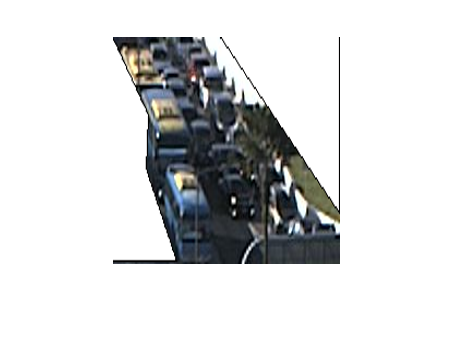

numImages = numel(imds.Labels);
idx = randperm(numImages,1);
figure
I = readimage(imds,idx);
imshow(I)

## Train the Neural Network

deepNetworkDesigner

## Classify Validation Images

[YPred,scores] = classify(trainedNetwork_1,imds);

Repeat process above to get 4 neural networks for different sections.

## Display four sample validation images with their predicted labels.

idx = randperm(numel(imds.Files),1);
imds.Files(idx);
I = readimage(imds,idx);
W1 = imcrop(I,[432.5 362.5 208 118]);
W1 = imresize(W1,[227 227]);
W2 = imcrop(I,[312.5 263.5 194 100]);
W2 = imresize(W2,[227 227]);
W3 = imcrop(I,[99.5 1.5 94 118]);
W3 = imresize(W3,[227 227]);
W4 = imcrop(I,[99.5 1.5 94 118]);
W4 = imresize(W4,[227 227]);
[YPred1,scores1] = classify(net,W1)
[YPred2,scores2] = classify(network2,W2)
[YPred3,scores3] = classify(network3,W3)
[YPred4,scores4] = classify(network4,W4)
imshow(I)
title(sprintf("Ori %s",string(imds.Labels(idx))));

Calculate the classification accuracy on the validation set. Accuracy is the fraction of labels that the network predicts correctly.

YValidation = imds.Labels;
%accuracy = mean(YPred == YValidation)

For tips on improving classification accuracy, see [Deep Learning Tips and Tricks](docid:nnet_ug#mw_b35bb367-38bf-4597-8e6b-479a2b3c408e).

*Copyright 2020 Kevin Chng, TechSource System*

function X = customreader(filename)
    X = imread(filename);
    X = imresize(X,[227 227]);
end